This file is for exam.

close all;
clear all;
clc;

mW = 1e3; % W to mW
kHz = 1e3;
MHz = 1e6;
GHz = 1e9;
km = 1e3;
c = 3e8;    % speed of light, m/s
k_B = 1.38e-23;          % Boltzmann’s constant, J/K

 EE583 hw2 ex4-3

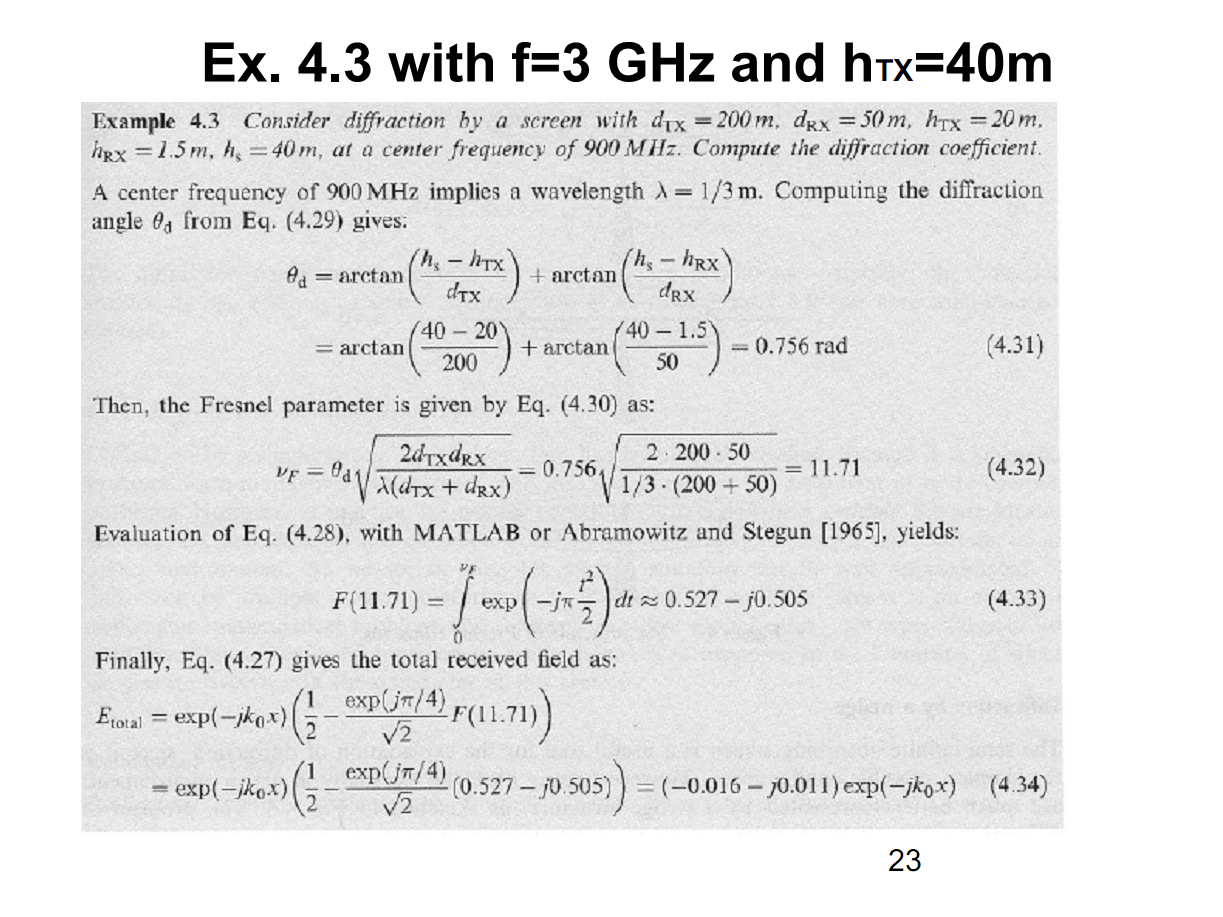

%{
f_carrier = 900*MHz;    % carrier frequency, Hz
hs = 60;
htx = 40;
hrx = 40;
dtx = 200;
drx = 200;

P =      1     1     0
     1     0     1
     0     1     1
     1     1     1



wavelength = c/f_carrier;
theta_d = atan((hs-htx)/dtx)+atan((hs-hrx)/drx)
vi_F = theta_d*(2*dtx*drx/wavelength/(dtx+drx))^0.5
coe = exp(1j*pi/4)/2^0.5
fun = @(x) exp(-1j.*pi.*x.^2./2);
% use func integral
F_vi_F = integral(fun,0,vi_F)
E_total_1 = 0.5-coe*F_vi_F % *exp(-jk0x)!!!!!!!!!!!must add this factor
%}

EE583 hw3-3

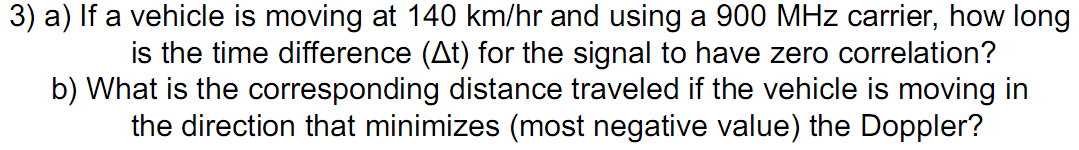

%{
delta_t = 0:0.0001:0.025;
f_c = 900e6;
v = 140/3.6;
v_max = f_c*v/c; % doppler frequence
% lamda = c/v;
y = besselj(0,2*pi*v_max*delta_t).^2;
% y = besselj(0,2*pi*delta_d/lamda).^2;
figure,
plot(delta_t,y)
delta_t0 = delta_t(find(diff(y)>0,1))
% % flag = 0;
% % if flag ==1
% % syms delta_t;
% % else
% % delta_t = -0.025:0.0001:0.025;
% % end
% % f_c = 900e6;
% % v = -140/3.6;
% % v_max = f_c*v/c;
% % y = besselj(0,2*pi*v_max*delta_t).^2;
% % if flag ==1
% %     y1=matlabFunction(y)
% % [delta_t]=fzero(y1,0.003);
% % % delta_t = solve(y == 0,delta_t)
% % else
% % figure,
% % plot(delta_t,y)
% % end
%}

EE583 hw5-1 calculate the multi-path variance, coherence bandwidth

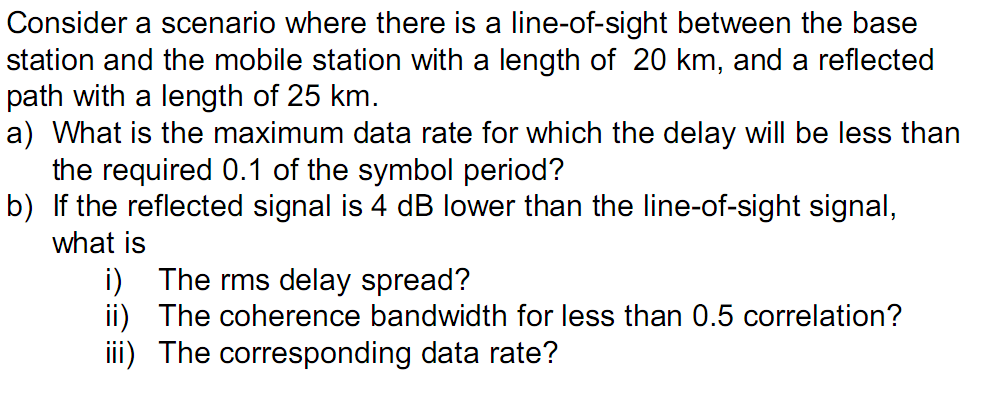

%{
% a)
syms fs; % symbols/s
coe_t = 0.1;
d1 = 10*km;
d2 = 13*km;
d3 = 15*km;
fs = solve(d3/c-d1/c==coe_t*1/fs)
% b)
syms tau positive;
a1 = 10^(0/10); % amplitude
a2 = 10^(0/10);
a3 = 10^(-6/10);
b1 = d1/c; % delay time
b2 = d2/c;
b3 = d3/c;
P = a1*dirac(tau-b1)+a2*dirac(tau-b2)+a3*dirac(tau-b3)
Pm = double(int(P,tau,-inf,inf))
Tm = double(int(P*tau,tau,-inf,inf)./Pm)
S = double(sqrt(int(P*tau^2,tau,-inf,inf)./Pm-Tm^2))
% f0 = 1/(5*S) % The coherence bandwidth for less than 0.5 correlation or for greater than 0.5 correlation
% no signal distortion is 0.5
f0 = 1/(50*S) % The coherence bandwidth for greater than 0.9 correlation

Rs = 1/T; symbols/s

for double side bandwidth,

W=(1+r)*Rs, r=(W-W0)/W0, in this case no filter, no ISI, r=0, W0 is filter bandwidth, W is system bandwidth, the filter is raised cosine filter

so W*T=1;

N_DSB = N0/2

for single side bandwidth or based band,

W=(1+r)*Rs/2, r=(W-W0)/W0, W0 is filter bandwidth, W is system bandwidth, the filter is raised cosine filter

for r=0, W>Rs/2, nyquist pulse, W is the minimum system bandwidth, bandwidth efficiency: 2 symbols/s/Hz, precise sampling at nT

% % y=subs(S,[a1,a2,b1,b2],[10^(0/10),10^(-4/10),10^(20e3/c),10^(25e3/c)]);
% % y1 = double(y)
%}

EE583 hw4-2 calculate the doppler distortion, coherence time

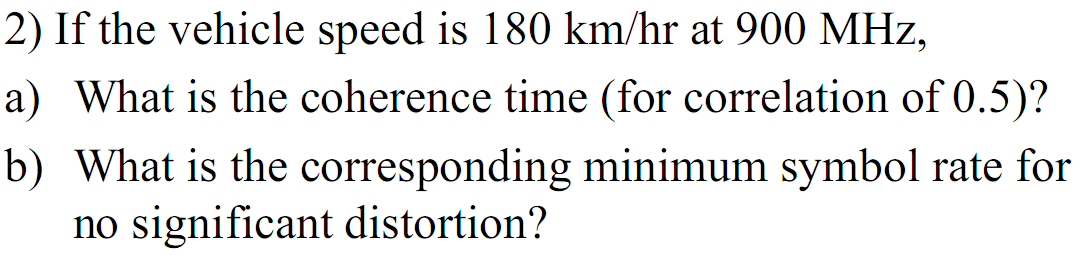

%{
% a)
f_c = 900*MHz;
v = 25;
fm = f_c*v/c % doppler frequence
T0 = 0.423/fm % coherence time for correlation of 0.5

if Rs is greater than 1/T0, the channel will not cause distortion due to motion

% b)
Rs = 1/T0
%}

fast or slow, frequence selective or flat

%{
syms W fm f0;
if fm<W<f0 || Tm<Ts<T0
    slow & flat
if W>fm && W>f0
    slow & frequence selective
if W<fm && W<f0
    fast & flat
if W<fm && W>f0
    fast & frequence selective
%}

EE583 hw3-2 Rayleigh faded signal

%{
m2s_db = 15; % db r_rms^2/r_min^2
m2s = 10^(m2s_db/10);
cdf = 1-exp(-1/m2s) % Pr(r<r_min)
%}

EE583 hw5-5 average BER for different modulation in fading channels

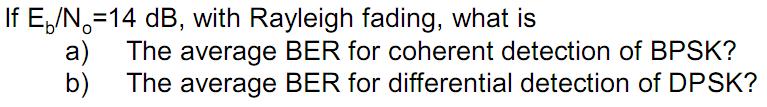

%{
EbN0_db = 10; % db
EbN0 = 10^(EbN0_db/10);
BER_ave = 0.5*(1-sqrt(EbN0/(1+EbN0))) % coherence detected BPSK antipodal
BER_ave = 0.5*(1-sqrt(EbN0/(2+EbN0))) % coherence detected orthogonal
BER_ave = 1/(2*(1+EbN0)) % differential detected DPSK antipodal
BER_ave = 1/(2+EbN0) % differential detected orthogonal
%}

BER for different modulatoin

%{
% for 2PAM, 1 bits/sympol, symbol energy is Eb
BER = qfunc(sqrt(2*EbN0)) % =Pb
% for 4QAM, 2 bits/sympol, symbol energy is 2Eb
BER = qfunc(sqrt(2*EbN0)) % =Pb
% for 8PSK, 3 bits/sympol, symbol energy is 3Eb
BER = 2/3*qfunc(sqrt(0.87*EbN0))
% for 16QAM, 4 bits/sympol, symbol energy is 4Eb
BER = 3/2*qfunc(sqrt(EbmaxN0/2.26)) % EbmaxN0 is for the signal at the corner
%}

calculate the link budget

%{
f_carrier = 5*GHz;    % carrier frequency, Hz 
if f_carrier == 'GSM'
    f_carrier = 900*MHz;
end
TX = 20;
TX_unit = 'dbm'; % W or mW or dbm or dbW
if TX ~= 'ans'
    switch TX_unit
        case 'w'
            TX = db(TX*mW,'p'); % dbm
        case 'mw'
            TX = db(TX,'p'); % dbm
        case 'dbw'
            TX = TX+30; % dbm
        case 'dbm'
            TX = TX;
    end
end
T_e = 0; % environmental temperature, K
if T_e == 0
    T_e = 290;
end
B = 20*MHz;            % bandwidth, Hz
TX_gain = 2;% db
RX_gain = 2;% db
losses = 93; %Losses in cables, combiners, etc. at the TX, db
Noise_Figure = 'ans'; % The noise ﬁgure of the RX, db
d_BP = 0; % if d<The breakpoint, m
d_RX = 0; % the distance over breakpoint, m
n = 0; % the path loss exponent
FadingMargin = 16; % db
SNR = 5; % db
RX  = 0; % dbm

wavelength = c/f_carrier;
if d_BP ~= 'ans'
    L_TX2BP = db((wavelength/(4*pi*d_BP))^2,'p'); % Path loss from TX to breakpoint, db
    %     L_TX2BP = round(L_TX2BP)
    if d_BP == 0
        L_TX2BP = 0;
    end
end
if d_RX ~= 'ans'
    L_BP2RX = db((d_BP/d_RX)^n,'p'); % Path loss from breakpoint to RX, db
    %     L_BP2RX = round(L_BP2RX)
    if d_RX == 0
        L_BP2RX = 0;
    end
end
P_thermal = k_B*T_e*B; % Thermal noise power, W
if B == 0
    P_thermal_dbm = 0;
else
    P_thermal_dbm = db(P_thermal*mW,'p') % dbm
    %     P_thermal_dbm = round(P_thermal_dbm)
end

if RX == 0
    RX = P_thermal_dbm;
end

if TX == 'ans'
    syms TX;
    TX = solve(TX+TX_gain-losses+L_TX2BP+L_BP2RX+RX_gain == RX+SNR+Noise_Figure+FadingMargin,TX); % dbm
    TX = double(TX)
end
if RX == 'ans'
    syms RX;
    RX = solve(TX+TX_gain-losses+L_TX2BP+L_BP2RX+RX_gain == RX+SNR+Noise_Figure+FadingMargin,RX); % dbm
    RX = double(RX)
end
if FadingMargin == 'ans'
    syms FadingMargin;
    FadingMargin = solve(TX+TX_gain-losses+L_TX2BP+L_BP2RX+RX_gain == RX+SNR+Noise_Figure+FadingMargin,FadingMargin); % dbm
    FadingMargin = double(FadingMargin)
end
if Noise_Figure == 'ans'
    syms Noise_Figure;
    Noise_Figure = solve(TX+TX_gain-losses+L_TX2BP+L_BP2RX+RX_gain == RX+SNR+Noise_Figure+FadingMargin,Noise_Figure); % dbm
    Noise_Figure = double(Noise_Figure)
end
if d_RX == 'ans'
    syms L_BP2RX;
    L_BP2RX = solve(TX+TX_gain-losses+L_TX2BP+L_BP2RX+RX_gain == RX+SNR+Noise_Figure+FadingMargin,L_BP2RX) % dbm
    L_BP2RX = double(L_BP2RX)
    syms d_RX positive;
    d_RX = solve(L_BP2RX == 10*log10((d_BP/d_RX)^n),d_RX);
    d_RX = double(d_RX)
end

P_iso = (lamda/(4*pi*d))^2*P_TX, P_RX is isotropic,

A_iso = lamda^2/(4*pi),

A_RX_e = lamda^2/(4*pi)*G_RX, A_RX_e is the effective area of receiving antenna

%}

Rayleigh Distance (Friis' Law for far field)

%{
lamda = c/f;
La = ; % La is the largest dimension of antenna
d_k = 2*La^2/lamda;
%}

EE583 hw6-1 Rayleigh fading with the same SNR for each branch

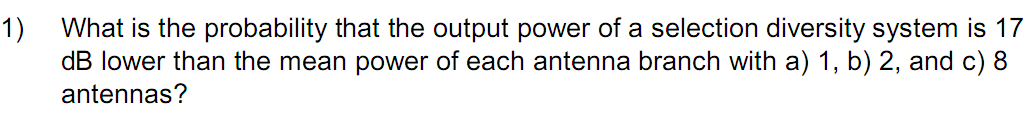

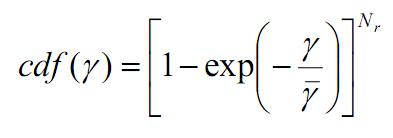

%{
% Nr = 8;
r_rm_db = -8; % r/r_mean, db, r is output power, rm is the mean power of each branch antenna
r_rm = 10^(r_rm_db/10);
cdf = 0.004;
syms Nr;
Nr = solve(cdf == (1-exp(-r_rm))^Nr,Nr);
Nr = double(Nr)
% cdf =  (1-exp(-r_rm))^Nr



%}
%{
r0 = 10^(4/10);
r_mean = 10^(12/10);
syms r;
cdf = r/(r_mean^2)*exp(-r/r_mean)
P = double(int(cdf,r,0,r0))
%}

EE583 hw6-2 signal optimum combinaiton

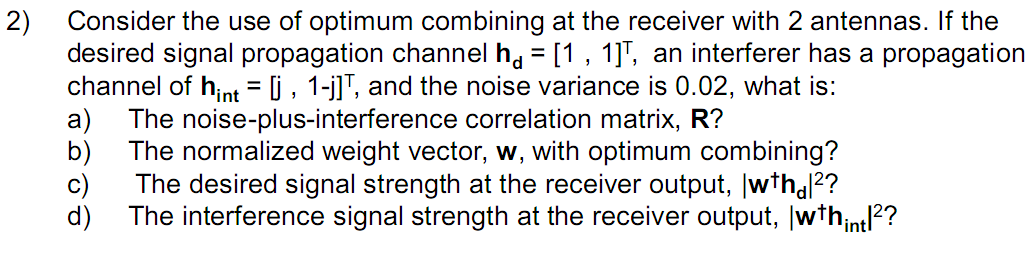

%{
N_receive = 3; % the number of receiving antennas
N_variance = 0.1; % sigma_n^2
N = N_variance*eye(N_receive); % the noise of antenna
hd = [1+0j, 1+0j, 1+0j].'; % desired signal propagation channel
hint(:,1) = [1+0j, 1+1j, 2+1j].'; % one interfer channel, =rk
hint(:,2) = [1+0j, -1-1j, 2-1j].'; % the second interfer channel
N_interfer = length(hint(1,:)); % the number of interfer
for n = 1:N_interfer
    E_i = hint(:,n)*hint(:,n)';
    N = E_i+N;
end
R = N % the noise-plus-interference correlation matrix
w_opt = R\hd; % the optimum combining weight, w_opt = inv(R)*hd
w = w_opt./norm(w_opt) % normalized weight vector, norm = sqrt(abs(a1)^2+abs(a2)^2+...+abs(an)^2)
rd = norm(w'*hd)^2 % the desired signal at the receiver output
ri1 = norm(w'*hint(:,1))^2 % the interference signal at the receiver output
ri2 = norm(w'*hint(:,2))^2
SINR = (w'*hd*hd'*w)/(w'*R*w);
SINR_db = db(SINR,'p');
%}

EE583 hw7-1 coding

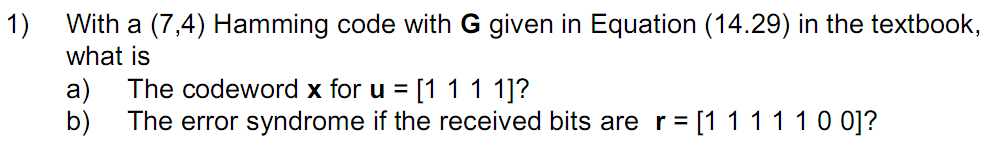

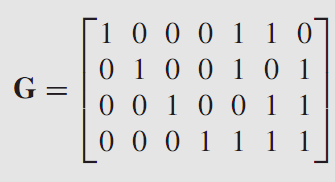

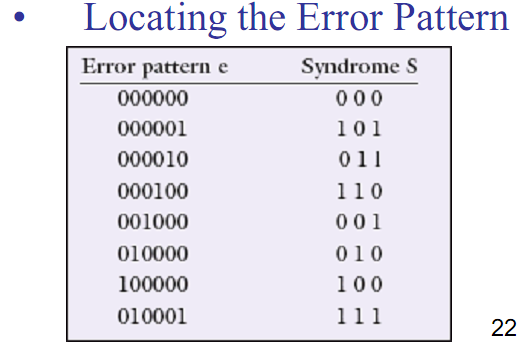

% %{
n = 7;
k = 4;
P(:,1) = [1 1 0 1]; % the parity check bits P的个数=n-k，数组中元素代表的不是码中parity码的个数
P(:,2) = [1 0 1 1]; % the parity check bits
P(:,3) = [0 1 1 1]; % the parity check bits
P
G = [eye(k),P]; % the KxN-dimensional generator matrix
% G = [P,eye(k)];
u = [1 0 1 1]; % the K-dimensional information vector
x = mod(u*G,2); % the N-dimensional code vector

r = [1 1 1 1 1 0 0]; % received bit sequence
% r = [1 0 0 0 1 0 1]; % received bit sequence
H = [P.',eye(n-k)]; % a parity check matrix
% H = [eye(n-k),P.'];
S = mod(r*H.',2); % a (N-K)-dimensional syndrome vector
%}

EE583 hw7-2 convolutional code

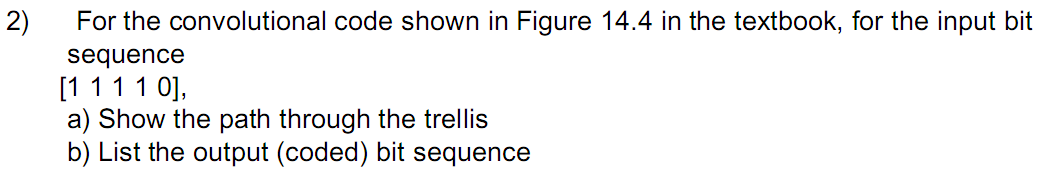

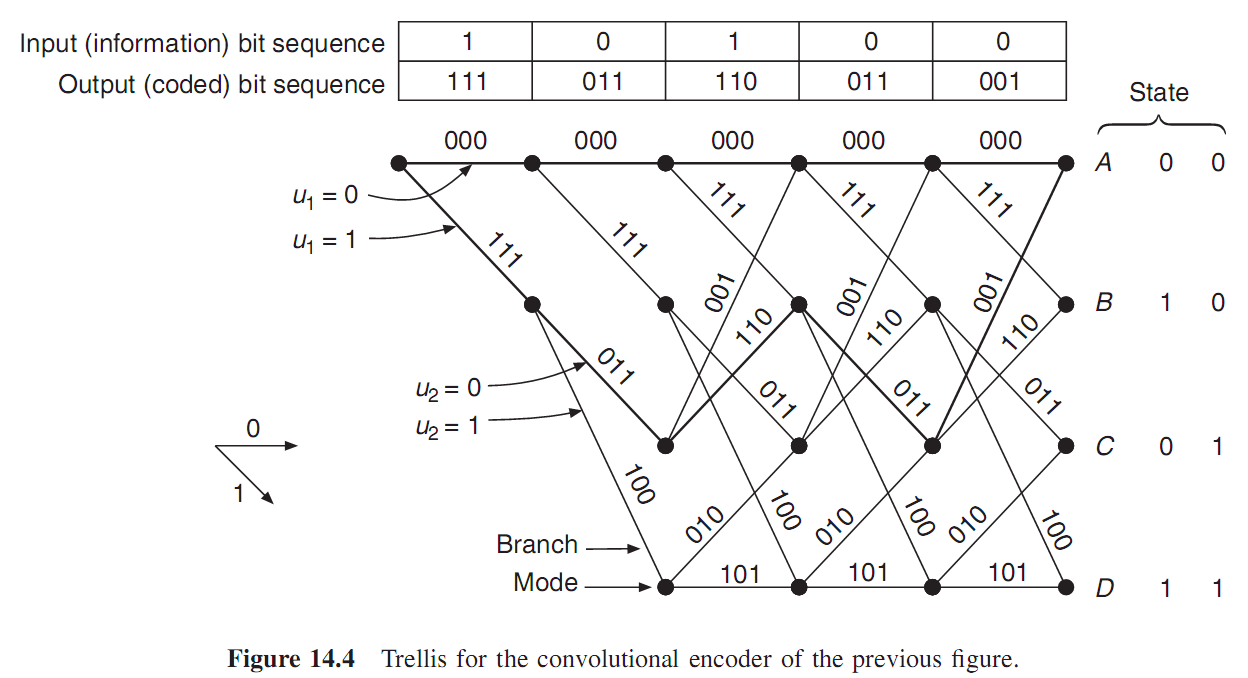

solution:

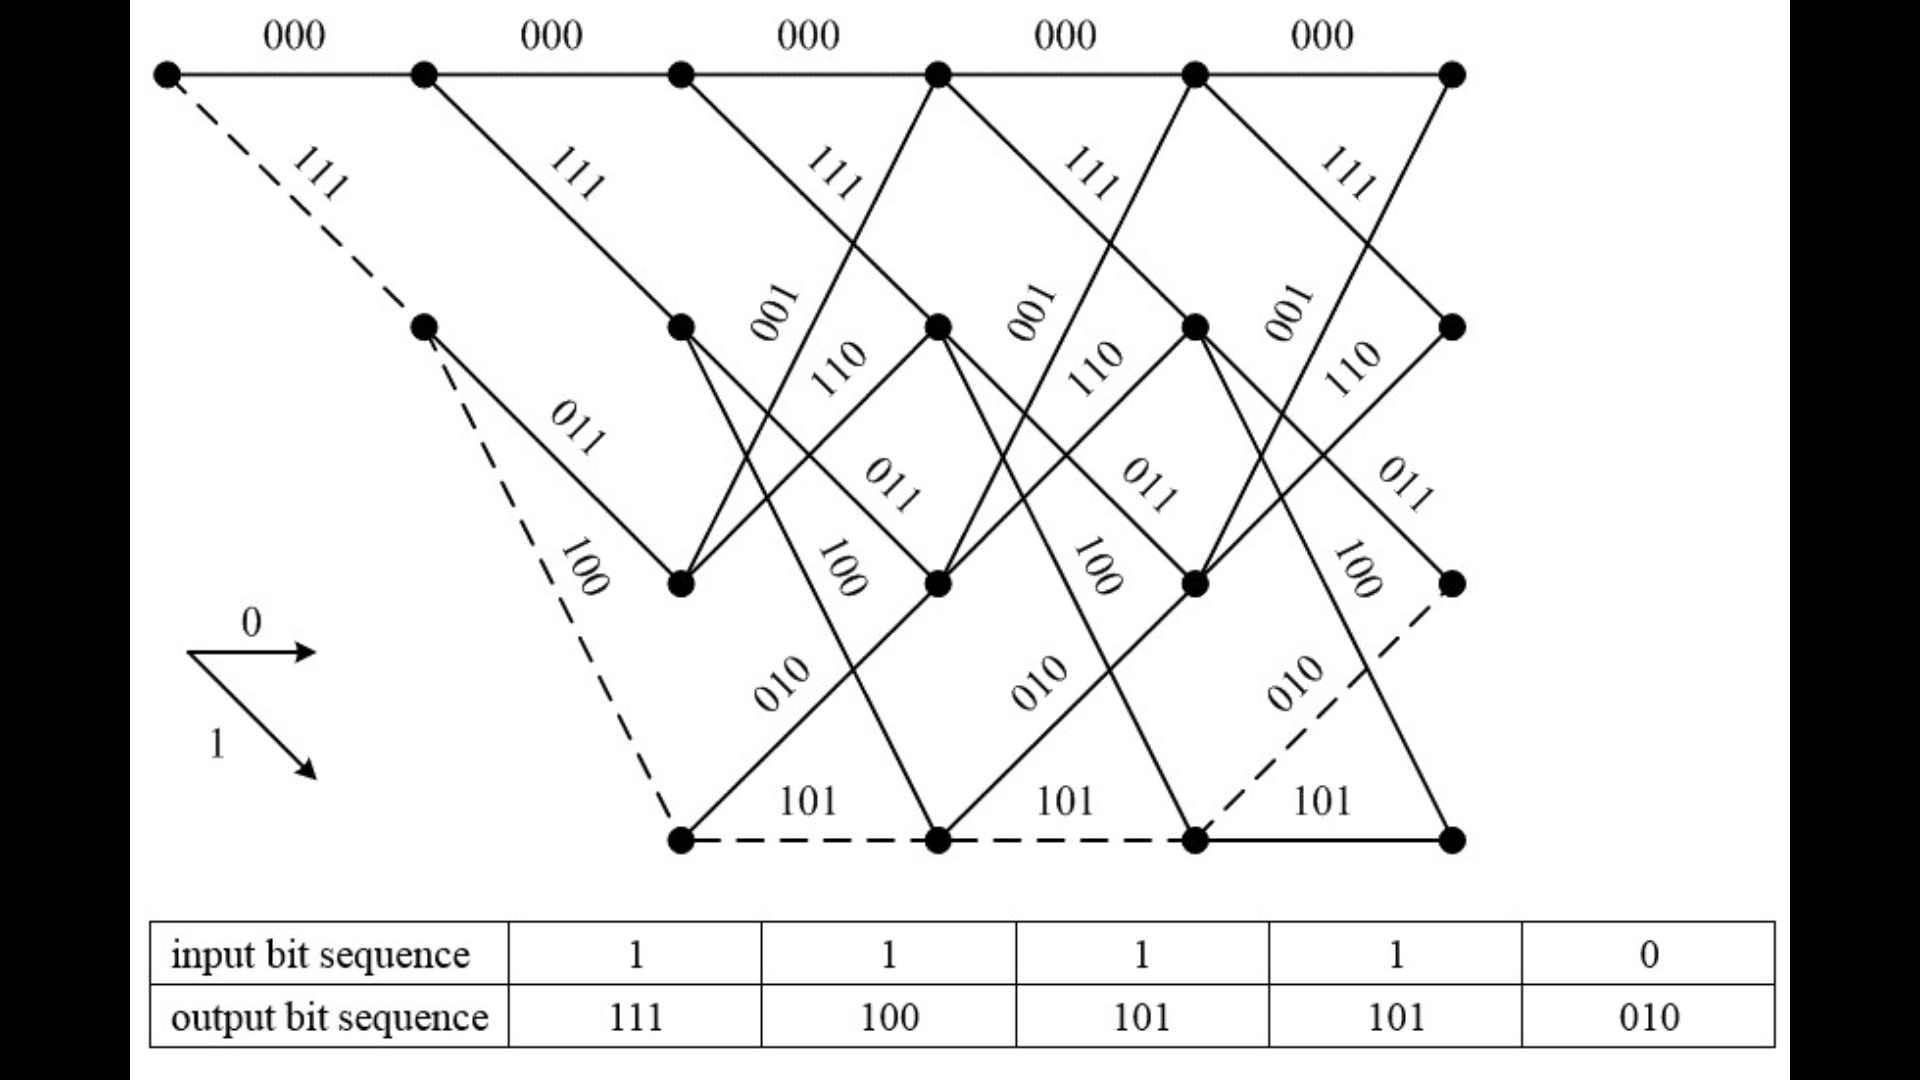

EE583 hw8 The Viterbi Equalizer

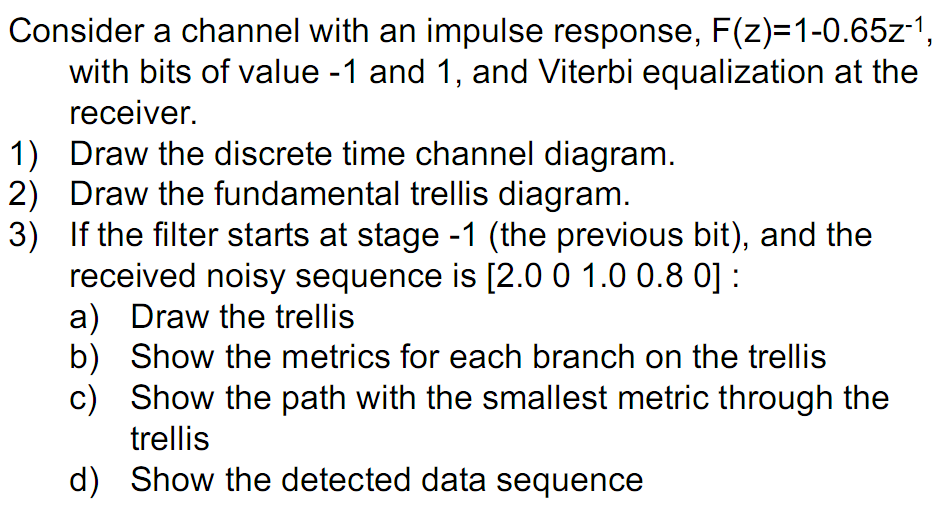

solution:

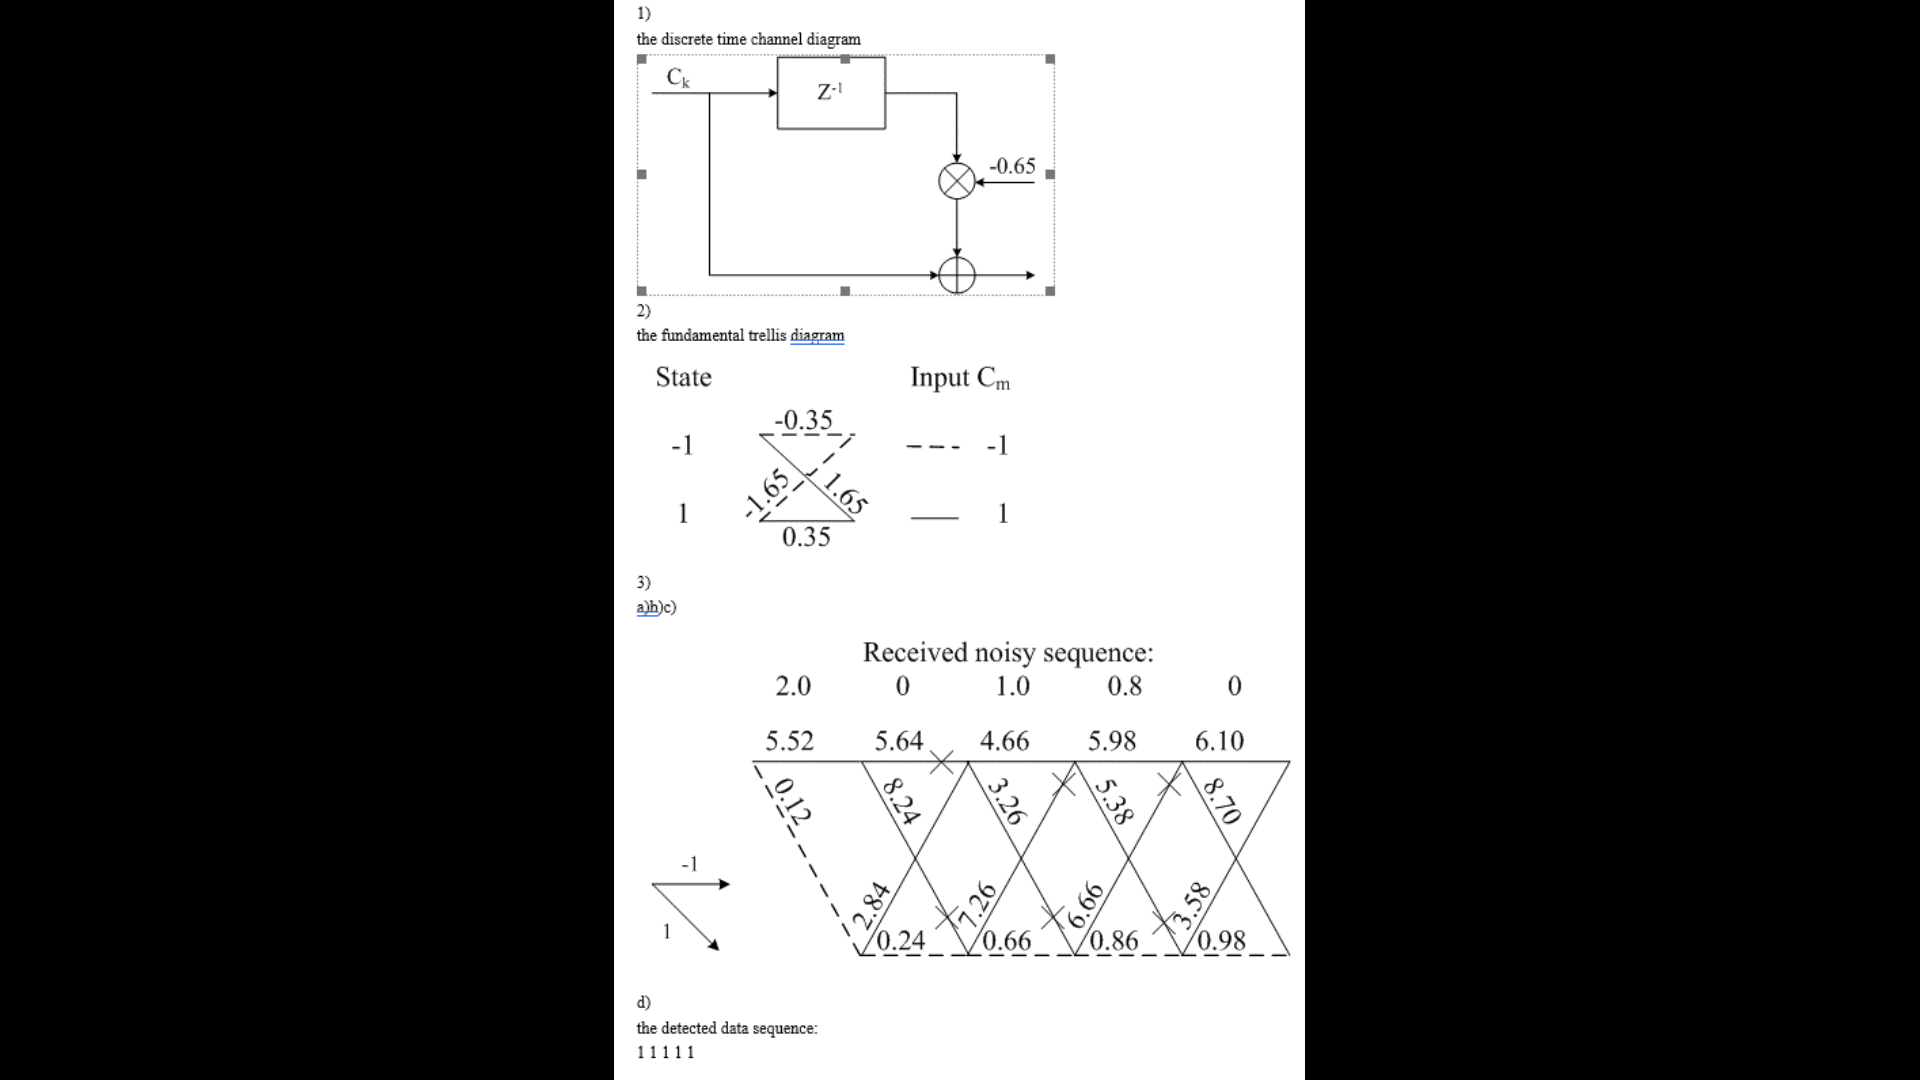

%{
x = 0;
y1 = (x-(-0.35))^2
y2 = (x-(1.65))^2
y3 = (x-(-1.65))^2
y4 = (x-(0.35))^2
%}